% ----------------- %
% Projet 1 SLAM EKF %
% ----------------- %

clear all; close all;


## Creation de la carte

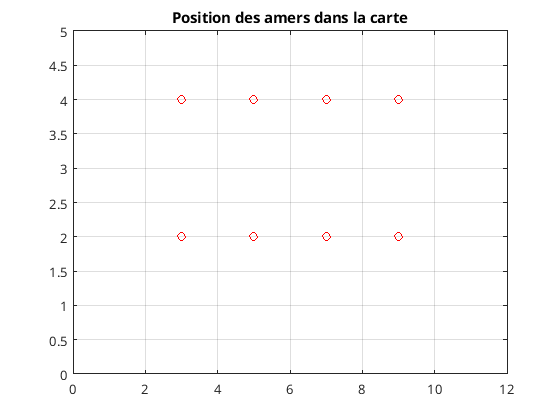

%Distances entre les amers
distXamer = 2;
disYamer = -2;

%Position des amers 
amer=[3 ;4];

for i=2:4
    amer(2*i-1) = amer(2*i-3)+distXamer;
    amer(2*i) = amer(2);
end
for i=5:8
    amer(2*i-1) = amer(2*i-9);
    amer(2*i) = amer(2)+disYamer;
end
%Affichage des amers
figure(1)
plot(amer(1:2:16), amer(2:2:16), 'or')
grid on 
axis([0 12 0 5])
title("Position des amers dans la carte")

## Génération des données réelles

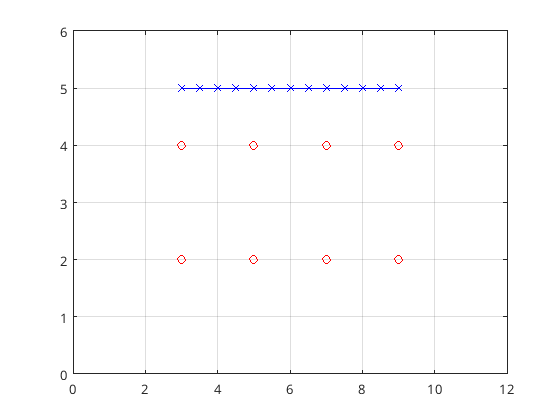

%Nombre d'instants
N = 13;

%Genération de la position du robot 
%Position initiale
Xr(:,1) = [3;5;0];
%Vecteur de commande
for i=1:N
    U(:,i)=[0.5;0;0];
end

%Boucle de generation de la trajectoire
for i=2:N
    Xr(:,i)=Xr(:,i-1)+[U(1,i-1)*cos(Xr(3,i-1))-U(2,i-1)*sin(Xr(3,i-1)) ; U(1,i-1)*sin(Xr(3,i-1))+U(2,i-1)*cos(Xr(3,i-1)) ; U(3,i-1)];
end

%Affichage de la trajectoire du robot 
figure(2)
plot(amer(1:2:16), amer(2:2:16), 'or')
hold on
plot(Xr(1,:), Xr(2,:), 'x-b')
axis([0 12 0 6])
grid on

%Generation des mesures 


## Filtrage

## Affichage des données